%%question three
clear
clc
u=linspace(0,2*pi,1000)';

a=0.1;
b=0.5;
x_=(b-cos(u)).*cos(u)+ (1-b);
y_=(b-cos(u)).*sin (u);
r=2*a*[x_,y_];

drdu = diff(r)./diff(u) % compute an approximation to the derivative

drdu =     0.0009   -0.1000
    0.0028   -0.1000
    0.0047   -0.0999
    0.0066   -0.0998
    0.0085   -0.0997
    0.0104   -0.0996
    0.0122   -0.0994
    0.0141   -0.0992
    0.0160   -0.0990
    0.0179   -0.0988


That = drdu./sqrt(sum(drdu.^2,2)) % compute the unit tangent vector

That =     0.0094   -1.0000
    0.0283   -0.9996
    0.0471   -0.9989
    0.0660   -0.9978
    0.0848   -0.9964
    0.1035   -0.9946
    0.1223   -0.9925
    0.1409   -0.9900
    0.1595   -0.9872
    0.1781   -0.9840


N = diff(That)./diff(u(1:end-1)) % compute the normal vector

N =     2.9993    0.0566
    2.9973    0.1132
    2.9941    0.1696
    2.9895    0.2260
    2.9837    0.2822
    2.9765    0.3383
    2.9681    0.3941
    2.9584    0.4496
    2.9475    0.5048
    2.9353    0.5598


Nhat = N./sqrt(sum(diff(drdu).^2,2)) % make it a unit normal

Nhat = 1.0e+03 *

    1.5896    0.0300
    1.5885    0.0600
    1.5867    0.0899
    1.5842    0.1198
    1.5810    0.1495
    1.5771    0.1792
    1.5724    0.2088
    1.5671    0.2382
    1.5610    0.2674
    1.5543    0.2964


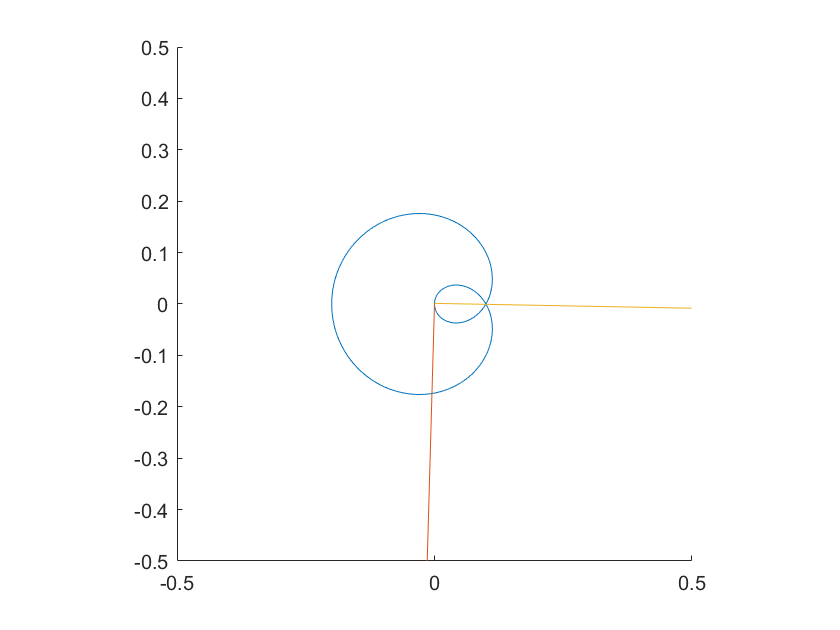

for i = 1:length(u)-2 % animate the unit tangent vector and unit normal vector
    clf
    hold on
    plot(r(:,1),r(:,2)) % plot the entire path
    quiver(r(i,1),r(i,2),That(i,1),That(i,2)) % plot That
    quiver(r(i,1),r(i,2),Nhat(i,1),Nhat(i,2)) % plot Nhat
    axis equal % equal axis so that it looks like a circle
    axis([-0.5 0.5 -0.5 0.5]) % plot domain large enough to see what is going on
    drawnow % force the plotting otherwise it will plot everything at once
end

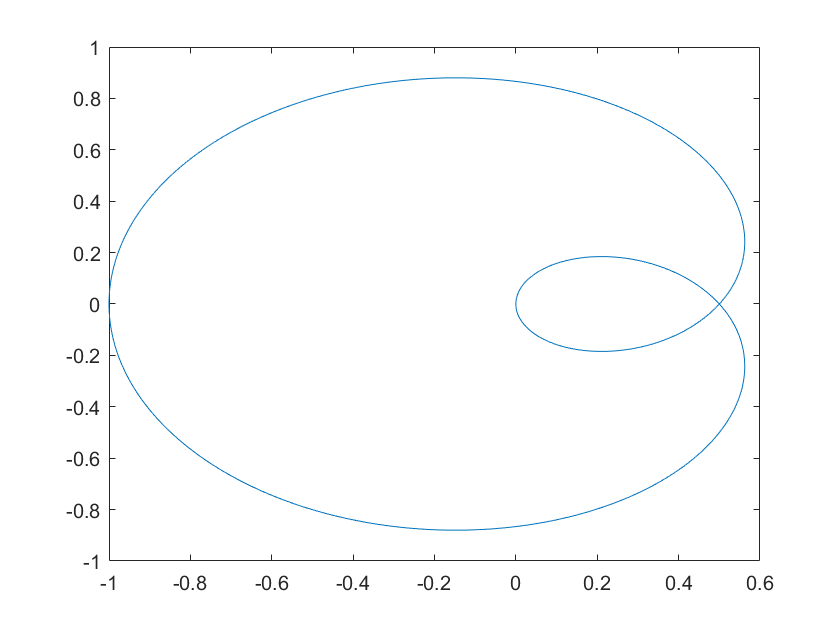


figure,plot(x_,y_)
hold on

drawnow